# Assignment 4: audio filtering – notch filter

gemaakt door: Nian Luisman

## Opdracht A & B

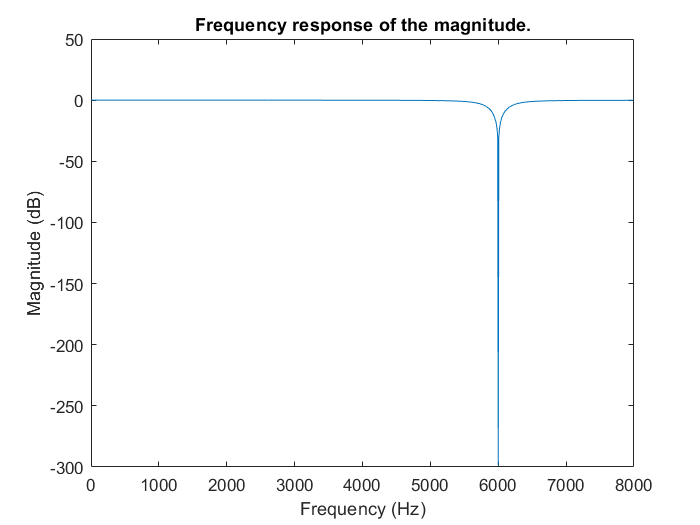


f_s = 16000; % sample frequentie .
f_i = 6000; %  frequentie van de stoortoon in het audiosignaal.

w_n = 2*pi*f_i/f_s; 
a = 0.90; 
k = (1 - 2*a*cos(w_n) + a^2) / (1 - 2*cos(w_n) + 1); % Bereken waarde voor 'k 'DC unit gain'.

number_of_points = 1000; % aantal punten'freqz'

a_digital = [1 -2*a*cos(w_n) a^2]; % noemer van het digitale filter (dit is in het z-domein).
b_digital = [k -2*k*cos(w_n) k]; % teller van het digitale filter (dit is in het z-domein).

[h_notch_filter, f] = freqz(b_digital, a_digital, number_of_points, f_s); % Bepaal de frequentie responsie van het digitale filter.

% Plot nu alle gegevens:
plot(f, 20*log10(abs(h_notch_filter))) % Plot de magnitude in dB van het digitale filter.
xlabel("Frequency (Hz)") % Een label voor de x-as.
ylabel("Magnitude (dB)") % Een label voor de y-as.
title("Frequency response of the magnitude.") % Een titel.

##  C & D

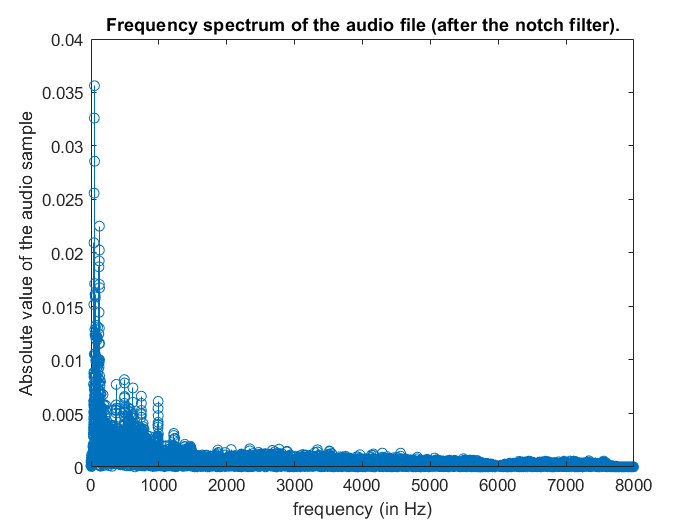



filename = "week3_sample_dist.wav"; 

[x, f_s] = audioread(filename); 

y = zeros(length(x), 1);

f_i = 6000; 
w_n = 2*pi*f_i/f_s;
a = 0.9; 
k = (1 - 2*a*cos(w_n) + a^2) / (1 - 2*cos(w_n) + 1); 

y(1) = 0; 
y(2) = 0; 


for n = 3:length(x)
    y(n) = 2*a*cos(w_n)*y(n - 1) - a^2*y(n - 2) + k*x(n) - k*2*cos(w_n)*x(n - 1) + k*x(n - 2); % Dit is de 'difference equation' toegepast in een lus.
end 

spec = fft(y);
N = length(spec)
spec = spec / N; 
spec_positive_notch = spec(1:N/2+1); 
freqs_notch = (f_s/N)*(0:N/2); 


stem(freqs_notch, abs(spec_positive_notch))
xlabel("frequency (in Hz)") 
ylabel("Absolute value of the audio sample") 
title("Frequency spectrum of the audio file (after the notch filter).")


audio_sample_norm = y / max(abs(y)); 

audiowrite("week4_sample.wav", audio_sample_norm, f_s) 
